# Sunny Pham, Chris Dong-Jae Shin, Lena Mourad

# #015161937, #014579836, #015975451

## Project 1, CECS 463

## 1.1

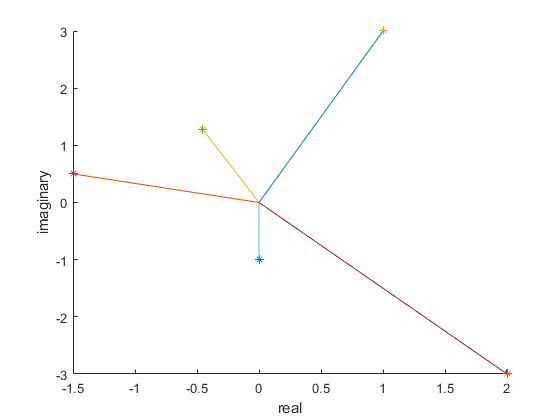


x= 1-2j;
y = -1+1j;

a = (x+y);
b = (x-y);
c = (x*y);
d = (x/y);
p = (x^y);

figure(1)
hold on
xlabel('real');
ylabel('imaginary');
plot(real(a), imag(a), '*')
plot(real(b), imag(b), '*')
plot(real(c), imag(c), '*')
plot(real(d), imag(d), '*')
plot(real(p), imag(p), '*')


plot([0 real(a)], [0 imag(a)])
plot([0 real(b)], [0 imag(b)])
plot([0 real(c)], [0 imag(c)])
plot([0 real(d)], [0 imag(d)])
plot([0 real(p)], [0 imag(p)])
hold off

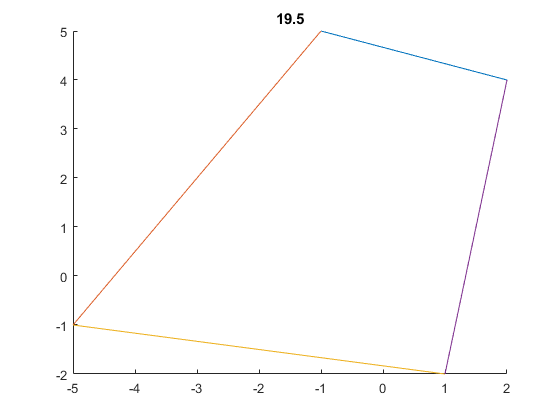




x = randi(5, 2);
y = randi(5, 2);
figure(2)
hold on
plot([x(1,1) -x(1,2)], [y(1,1) y(1,2)])
plot([-x(1,2) -x(2,2)], [y(1,2) -y(2,2)])
plot([-x(2,2) x(2,1)], [-y(2,2) -y(2,1)])
plot([x(2,1) x(1,1)], [-y(2,1) y(1,1)])

p1 = abs(x(1,1) + x(1,2)) * abs(y(1,1) - y(1,2));
p2 = abs(x(1,2) - x(2,2)) * abs(-y(1,2) - y(2,2));
p3 = abs(-x(2,2) - x(2,1)) * abs(-y(2,2) + y(2,1));
p4 = abs(-x(2,1) + x(1,1)) * abs(y(2,1) + y(1,1));
a = .5 * (p1 + p2 + p3 + p4);
title(a)
hold off

## 1.2 & 1.3



figure(3)
k = 0:pi/100:2*pi;
x = 3 * exp(1j * 45 * pi/180);
y = 2 * exp(1j * (-150-90) * pi/180);

x_r = real(x);
x_i = imag(x);
y_r = real(y);
y_i = imag(y);

z_r = x_r + y_r;
z_i = x_i + y_i;

z_amplitude = sqrt(z_r^2 + z_r^2)

z_amplitude = 1.5858

z_phaseangle = atan(z_i/z_r)*180/pi

z_phaseangle = 73.7752

 str = {strcat('amplitude = ' , num2str(z_amplitude), ' phase angle = ', num2str(z_phaseangle))}

str = 1×1 cell array
    {'amplitude =1.5858 phase angle =73.7752'}


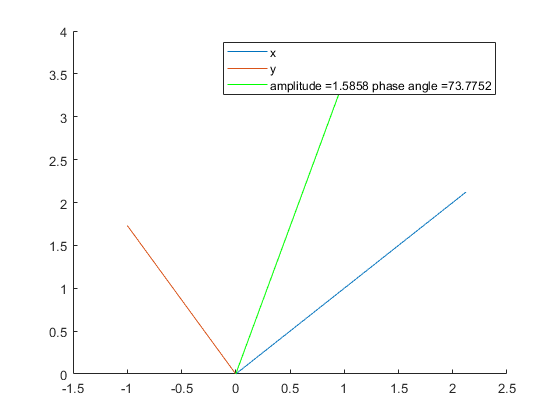


hold on
plot([0 x_r], [0 x_i], 'DisplayName', 'x')
plot([0 y_r], [0 y_i], 'DisplayName', 'y')
plot([0 z_r], [0 z_i], 'g', 'DisplayName', str{:})
hold off

legend()

## 1.4

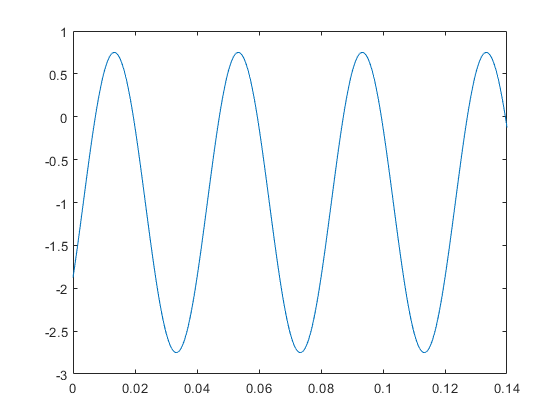


%A = 2.5
%offset = -1.25
% theta appx = pi/6
% omega appx = 200
figure(4)
t = [0:0.0002:0.14];
A = 1.75;
offset = -1;
theta_approx = 30*5*pi/3;
omega_approx = -2*pi/3;
y = A * cos(theta_approx * t + omega_approx) + offset;
plot(t, y)

## 2.1

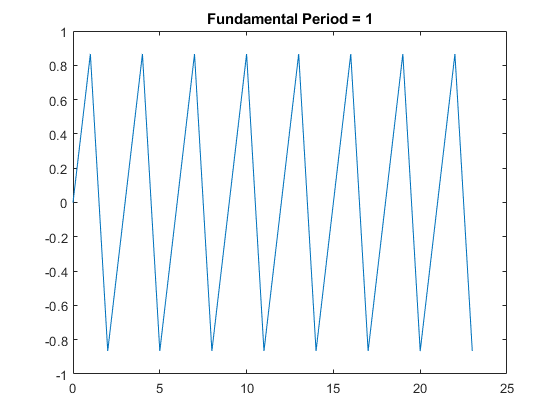

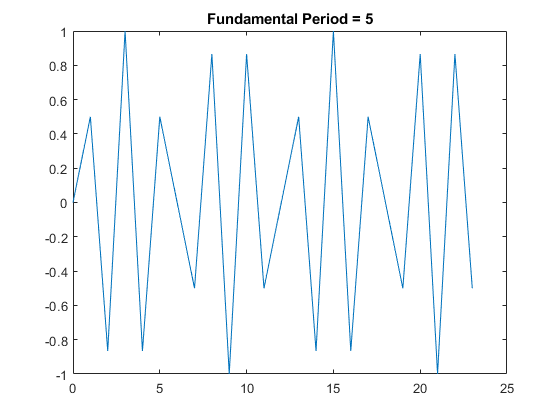

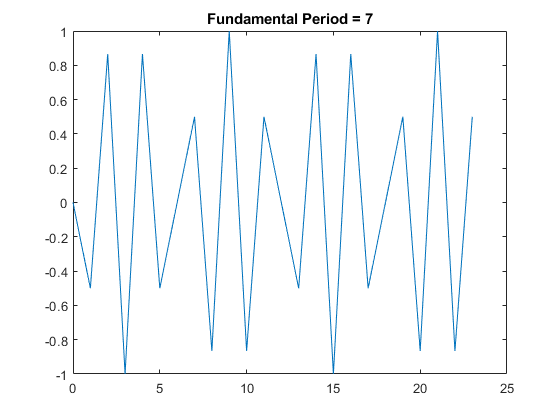

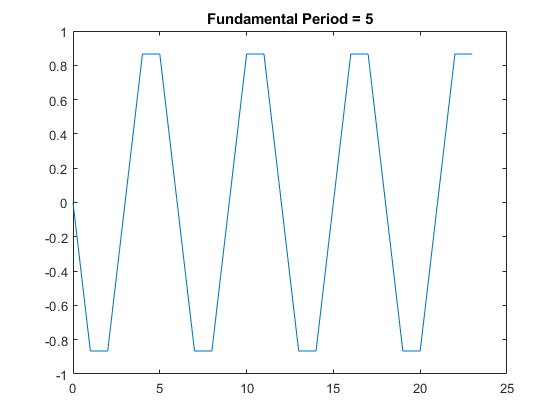

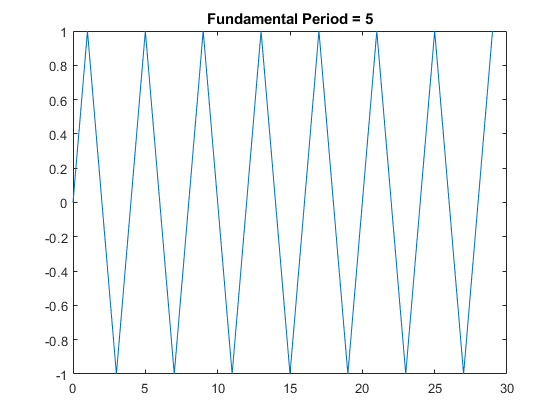



N = 12;
for M = [4, 5, 7, 10, 15]
    figure
    
    if M < N
        n = 0:2*N-1;
    else
        n = 0:2*M-1;
    end
    x_m = sin(2*pi*M*n/N);
    [P Q] = rat(M/N);
    plot(n, x_m, '-')
    str = sprintf('Fundamental Period = %d', P);
    title(str)
    
end

## 2.2

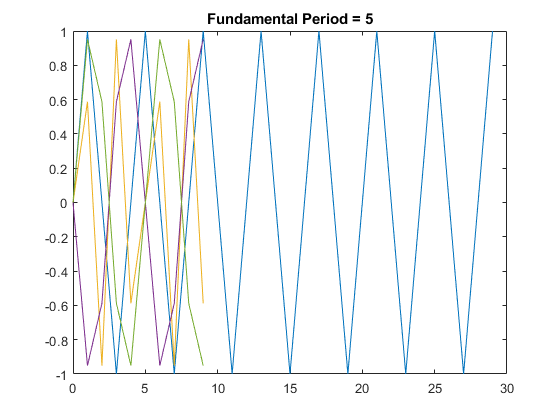



figure(9)
n = 0:9;
hold on
for k = [1, 2, 4, 6]
    w = 2*pi*k/5;
    x_k = sin(w*n);
    plot(n, x_k, '-')
end
hold off


%signal for k = 2 and k = 6 are identical, becuase 12/5pi reduces to 2/5pi


## 2.3

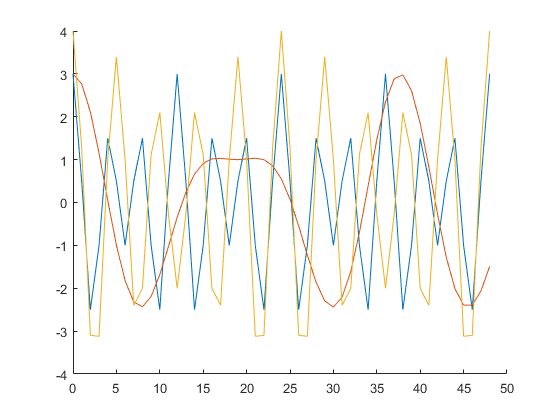


figure(10)
N = 6;
n = 0:48;
x_1 = cos(2*pi*n/N) + 2*cos(3*pi*n/N);
x_2 = 2*cos(2*n/N) + cos(3*n/N);
x_3 = cos(2*pi*n/N) + 3*cos(5*pi*n/2/N);

hold on
plot(n, x_1, '-')
plot(n, x_2, '-')
plot(n, x_3, '-')

hold off

% period of x_1 = 38
% period of x_2 = 24
% period of x_3 = 24


## 2.4

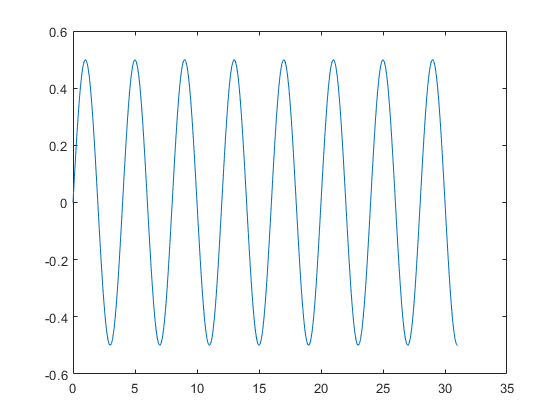


n = 0:0.1:31;

figure(9)
x_1 = sin(pi*n/4) .*cos(pi*n/4);
% same equation but using the hint
%x_1 = (sin(pi*n/4 + pi*n/4) + sin(pi*n/4 + pi*n/4))/2;
plot(n,x_1, '-')

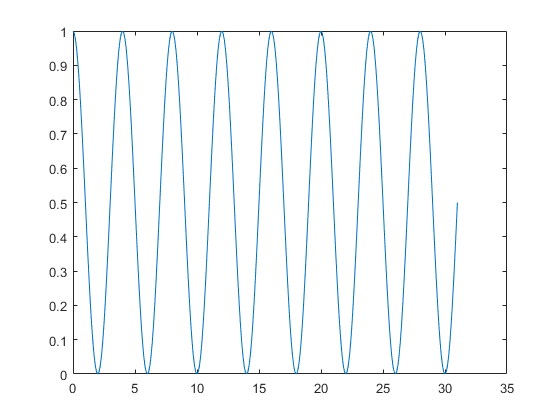


figure(10)
x_2 = (cos(pi*n/4)).^2;
plot(n,x_2, '-')

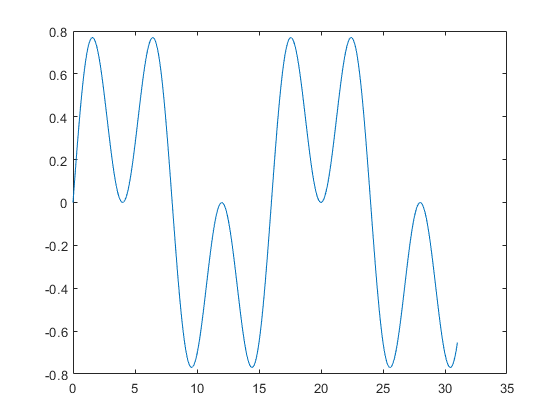


figure(11)
x_3 = sin(pi*n/4) .* cos(pi*n/8);
plot(n,x_3, '-')

## 2.5

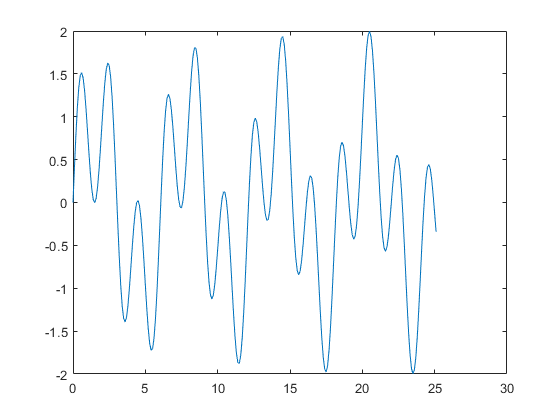


figure(12)
n = 0:0.1:8*pi;
plot(n, sin(n) + sin(pi*n), '-')

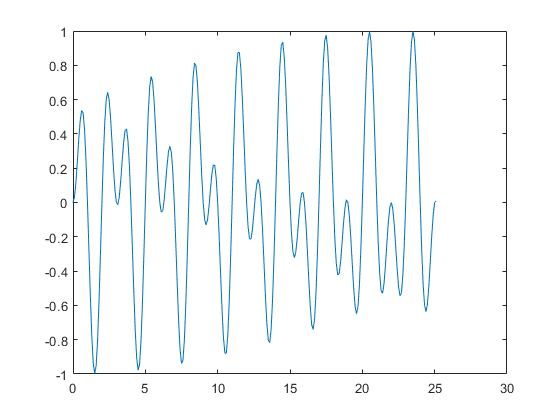



figure (13)
plot(n, sin(n) .* sin(pi *n), '-')

## 3.1

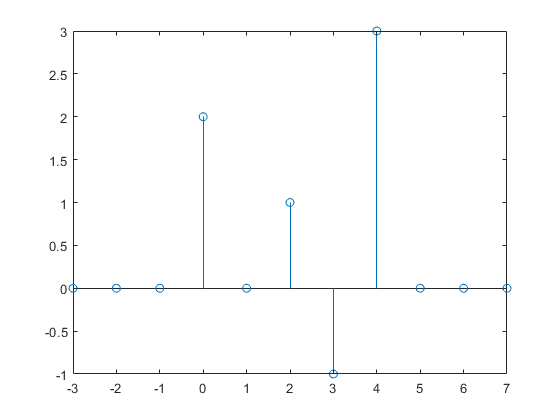


figure;
n = -3:7;
x_n(-3 <= n <= 7) = 0;
x_n(n == 0) = 2;
x_n(n == 2) = 1;
x_n(n == 3) = -1;
x_n(n == 4) = 3;


stem(n, x_n)

## 3.2


figure;

[y1, n1] = sigshift(x_n, n, 2);
[y2, n2] = sigshift(x_n, n, -1);
[y3, n3] = sigshift(x_n, -n, 0);
[y4, n4] = sigshift(x_n, -n, 1);


## 3.3

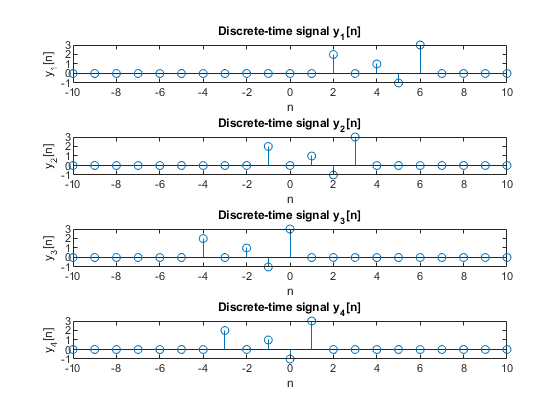


n_ref = -10:10;
y_ref = zeros(1, 21);

[y1, n1] = sigadd(y1, n1, y_ref, n_ref);
[y2, n2] = sigadd(y2, n2, y_ref, n_ref);
[y3, n3] = sigadd(y3, n3, y_ref, -n_ref);
[y4, n4] = sigadd(y4, n4, y_ref, -n_ref);


subplot(4, 1, 1);
stem(n1, y1)
title('Discrete-time signal y_1[n]')
ylabel('y_1[n]')
xlabel('n')
subplot(4, 1, 2);
stem(n2, y2)
title('Discrete-time signal y_2[n]')
ylabel('y_2[n]')
xlabel('n')

subplot(4, 1, 3);
stem(n3, y3)
title('Discrete-time signal y_3[n]')
ylabel('y_3[n]')
xlabel('n')

subplot(4, 1, 4);
stem(n4, y4)
title('Discrete-time signal y_4[n]')
ylabel('y_4[n]')
xlabel('n')

## 4.1

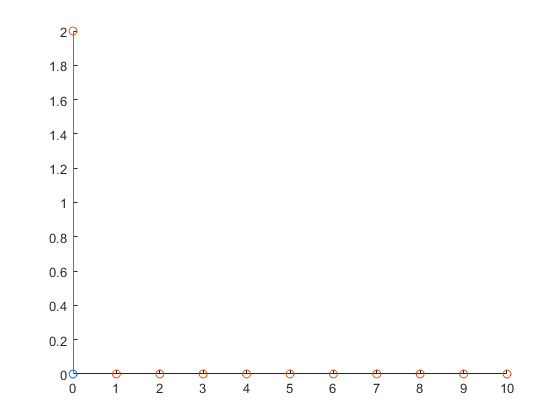




A = 2;
B = -1;

[x_1, n] = impseq(0, 0, 10);
[x_2, n] = impseq(0, 0, 10);
x_2 = x_2 * 2;

y_1 = sin((pi/2*(A*x_1+B*x_2)));
y_2 = A * sin(pi/2*x_1) + B * sin(pi/2*x_2);


figure;
hold on
stem(n, y_1)
stem(n, y_2)
hold off

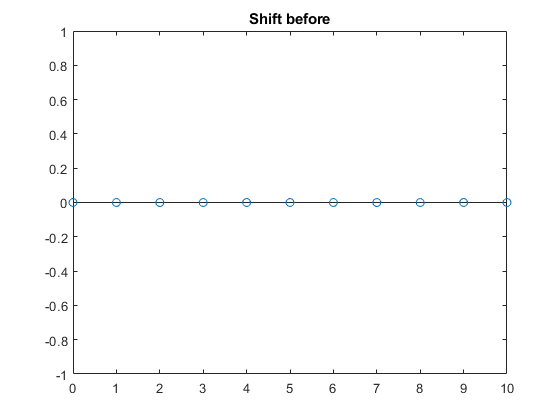


%4.1b

n = 0:10;
x = impseq(0, 0, 10);

nx = n .* x;

nx_shift_last = sigshift(nx, n, 1);

x_shift_first = sigshift(x, n, 1);

nx_shift_first = n .* x_shift_first;

figure();
stem(n, nx_shift_first)
title('Shift before')

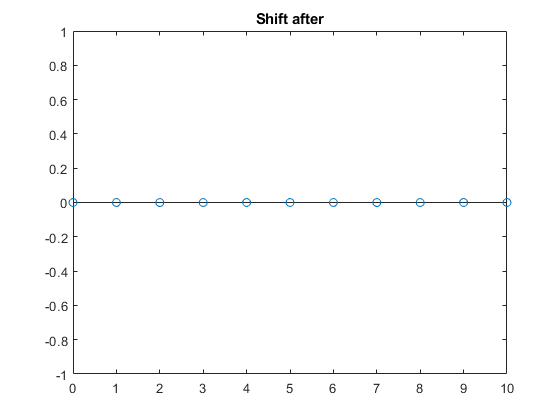


figure();
stem(n, nx_shift_last)
title('Shift after')


%4.1c

n_ref = -10:10;
y_ref = zeros(1, 21);
[x_n, n] = stepseq(0, -5, 9);

n =     -5    -4    -3    -2    -1     0     1     2     3     4     5     6     7     8     9


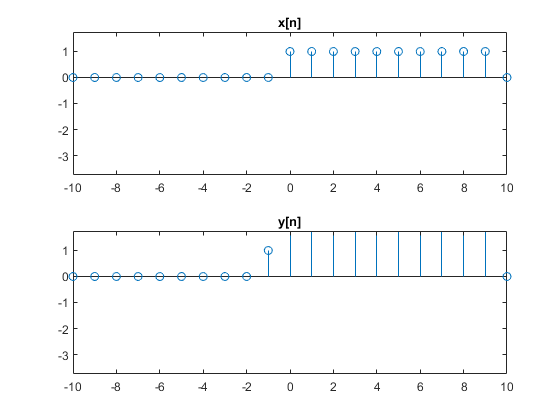


[x_n_shift1 n_shift1] = sigshift(x_n, n, -1);

x_n_shift1 = [x_n_shift1, [1]];
n_shift1 = [n_shift1, [9]];

[y_n n_f] = sigadd(x_n, n, x_n_shift1, n_shift1);

[y_n, n_f] = sigadd(y_n, n_f, y_ref, n_ref);
[x_n, n_ref] = sigadd(x_n, n, y_ref, n_ref);

figure();

subplot(2, 1, 1);
stem(n_f, x_n)
axis([-10, 10, min(y)-1, max(y)+1])
title('x[n]')


subplot(2, 1, 2);
stem(n_f, y_n)
axis([-10, 10, min(y)-1, max(y)+1])
title('y[n]')

## 5.1

% in the functions below


## 5.2


a = 1;
N = 31;
n = 0:N - 1;
yn1 = zeros(1,31);
yn2 = zeros(1,31);


x_n1 = impseq(0,0,N);
x_n2 = stepseq(0,0,N);

n =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31


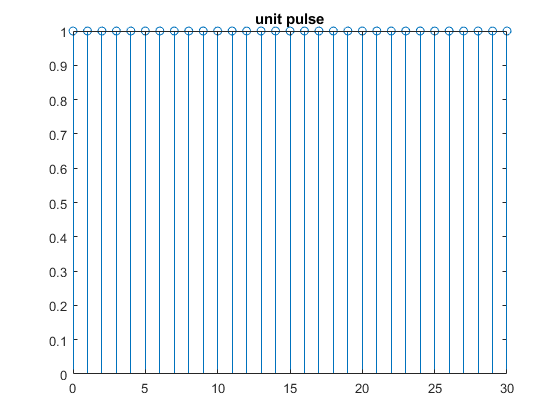



%y[-1] = 0
yn1(1) = diffeqn(a, x_n1(1), 0);
yn2(1) = diffeqn(a, x_n1(1), 0);

for i = 2:31
    yn1(i) = diffeqn(a, x_n1(i), yn1(i-1));
    yn2(i) = diffeqn(a, x_n2(i), yn2(i-1));
end

yn1 = sigshift(yn1, n, -1);
yn2 = sigshift(yn2, n , -1);

figure

stem(n, yn1)
title('unit pulse')

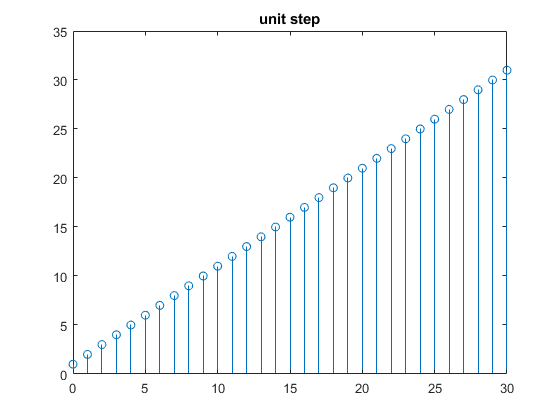



figure

stem(n, yn2)
title('unit step')

## 5.3

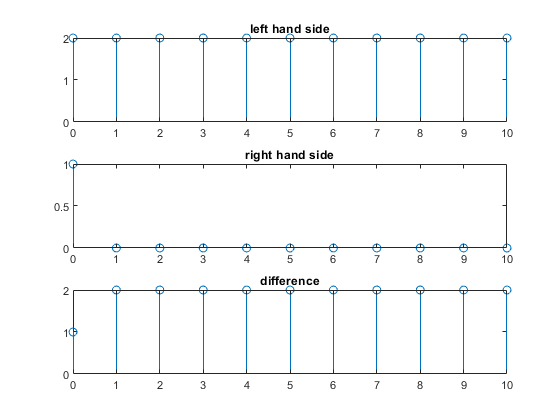


a = 1;


A = 1;
B = 1;

N = 11;

% N-1 because of indexing
n = 0:N-1;

x1 = impseq(0,0,11);
x2 = 2*impseq(0,0,11);
xn = A*x1 + B *x2;

%ylhs (left hand side)
ylhs = zeros(0,N);
rhs_y1 = zeros(0,N);
rhs_y2 = zeros(0,N);

% y[-1] = -1
ylhs(1) = diffeqn(a, xn(1), -1);
rhs_y1(1) = diffeqn(a, x1(1), -1);
rhs_y2(1) = diffeqn(a, x2(1), -1);

for i = 2: N
    ylhs(i) = diffeqn(a, xn(i), ylhs(i-1));
    rhs_y1(i) = diffeqn(a, x1(i), rhs_y1(i-1));
    rhs_y2(i) = diffeqn(a, x2(i), rhs_y1(i-1));
end

yrhs = A*rhs_y1 + B*rhs_y2;

figure(3)
subplot(3,1,1);
stem(n, ylhs)
title('left hand side')


subplot(3,1,2);
stem(n, yrhs)
title('right hand side')

subplot(3,1,3);
stem(n, ylhs -yrhs)
title('difference')

% two graphs are not identical because, the operations that are done in
% between tweaks the output of the output before the FOAR


## 5.4

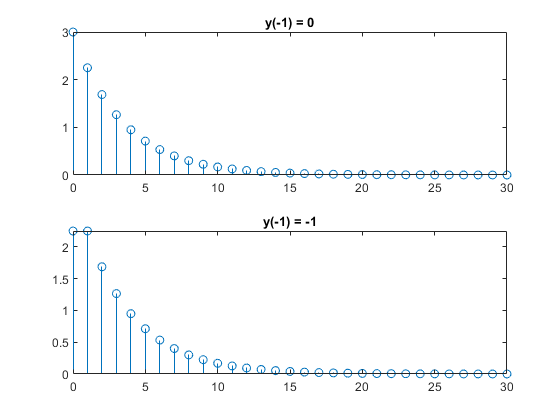


a = 3/4;
N = 31;
x_n = impseq(0,0,N);
n = 0:N-1;

y_1 = zeros(0,N);
y_2 = zeros(0,N);

y_1(1) = diffeqn(a, xn(1), 0);
y_2(1) = diffeqn(a, xn(1), -1);

for i = 2: N
    y_1(i) = diffeqn(a, x_n(i), y_1(i-1));
    y_2(i) = diffeqn(a, x_n(i), y_1(i-1));
end

figure()
subplot(2,1,1);
stem(n, y_1)
title('y(-1) = 0')

subplot(2,1,2);
stem(n, y_2)
title('y(-1) = -1')


%they are different in value, when y(-1) = 0 the value in the beginning is
%bigger. Limiting value of the output as n gets large the y beocmes smaller

function y = diffeqn(a, x, yn1)
    % FOAR

    y = a *yn1 + x;
end

function [x,n] = stepseq(n0, n1, n2)
% Generate x(n) = (n-n0); n1<n<n2
%
% [x,n] = stepseq(n0,n1,n2)
%
n = [n1:n2]
x = [(n-n0) >= 0];
end

function [x,n] = impseq(n0, n1, n2)
% Generate x(n) = delta (n-n0); n1 < n0 < n2
%
% [x,n] = impseq(n0,n1,n2)
%
n = [n1:n2];
x = [(n-n0) == 0];
end

function [y,n] = sigadd(x1, n1, x2, n2)
% Implements y(n) = x1(n) + x2(n)
%
% [y,n] = sigadd(x1, n1, x2, n2)
% x1 = first sequence over n1
% x2 = second sequence over n2 (n2 can be different than n1)
%
n = min(min(n1), min(n2)): max(max(n1),max(n2));
y1 = zeros(1, length(n));
y2 = y1;
y1(find((n>=min(n1)) & (n<=max(n1)) == 1)) = x1;
y2(find((n>=min(n2)) & (n<=max(n2)) == 1)) = x2;
y = y1 + y2;
end

function [y,n] = sigmult(x1, n1, x2, n2)
n = min(min(n1), min(n2)):max(max(n1), max(n2));
y1 = zeros(1, length(n));
y2 = y1;
y1(find((n>=min(n1)) & (n<=max(n1)) == 1)) = x1;
y2(find((n>=min(n2)) & (n<=max(n2)) == 1)) = x2;
y = y1 .* y2;
end

function [y,n] = sigshift(x, m, k)

n = m + k;
y = x;
end

function [y,n] = sigfold(x, n1)

y = fliplr(x);
n = -fliplr(n1);

end

function [xe, xo, m] = evenodd(x,n)

if any(imag(x) ~= 0)
    error('x is not a real sequence')  
end

m = -fliplr(n);
m1 = min([m, n]);
m2 = max([m, n]);
m = m1:m2;
nm = n(1)-m(1);
n1 = 1:length(n);
x1 = zeros(1, length(m));
x1(n1+nm) = x;
x = x1;
xe = 0.5*(x + fliplr(x));
xo = 0.5*(x-fliplr(x));
end

function [y, ny] = conv_m(x, nx, h, nh)

nyb = nx(1) + nh(1);
nye = nx(end) + nh(end);
ny = [nyb:nye];
y = conv(x,h);
end

